**The For Loop**

for i = 1:5
    fprintf('%d\n', i)
end

1
2
3
4
5


disp([1:5]')

     1
     2
     3
     4
     5



disp([1:5])

     1     2     3     4     5



for i = 0:50:200
    fprintf('%d\n', i)
end

0
50
100
150
200


for i = 0:50:200
    fprintf('%3d\n', i)
end

  0
 50
100
150
200


for i = 1:5
    fprintf('*\n')
end

*
*
*
*
*


repelem('*', 10)'

ans = 10×1 char array
    '*'
    '*'
    '*'
    '*'
    '*'
    '*'
    '*'
    '*'
    '*'
    '*'


**Preallocation a Vector**

n = randi([4 8]);
vec = zeros(1, n);

for i = 1:n
    theNumber = input('Enter a number: ');
    vec(i) = theNumber;
end 

fprintf('The vector is: \n')

The vector is: 


disp(vec)

    23    14   189    39



**Subplot(r, c, n) = a subplot matrix, starting numbering rowise in upper left corner (r = numrows, c = numcols of plots in the window)**

y =          0    0.3247    0.6142    0.8372    0.9694    0.9966    0.9158    0.7357    0.4759    0.1646   -0.1646   -0.4759   -0.7357   -0.9158   -0.9966   -0.9694   -0.8372   -0.6142   -0.3247   -0.0000


y =          0    0.1604    0.3167    0.4647    0.6007    0.7212    0.8230    0.9035    0.9605    0.9927    0.9992    0.9798    0.9350    0.8660    0.7746    0.6631    0.5345    0.3920    0.2393    0.0805   -0.0805   -0.2393   -0.3920   -0.5345   -0.6631   -0.7746   -0.8660   -0.9350   -0.9798   -0.9992   -0.9927   -0.9605   -0.9035   -0.8230   -0.7212   -0.6007   -0.4647   -0.3167   -0.1604   -0.0000


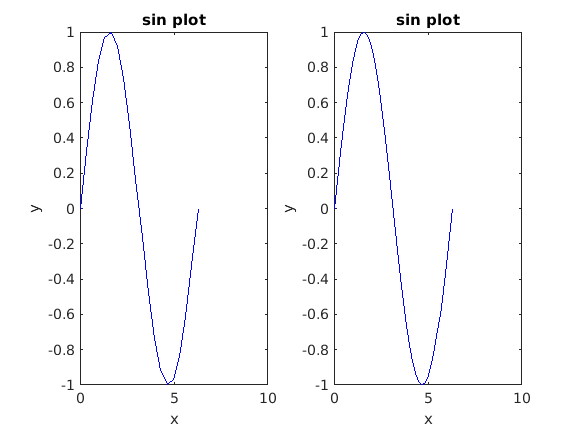


for i = 1:2
    x = linspace(0, 2*pi, 20*i);
    y = sin(x)
    
    % making the particular ith plot active so we can
    % use the plotting functions and make the plot
    % inside this ith window. 
    subplot(1, 2, i)
    % note - 1-2 never changes, same as i-range. 
    
    
    plot(x, y, 'b-')
    xlabel('x')
    ylabel('y')
    title('sin plot')
end 

**Nested For Loops**

% prints a box of stars
rows = 3;
columns = 5;

% loop over rows
for i = 1:rows
    %for every row loop to print *'s and then one \n
    for j = 1:columns
        fprintf('*')
    end
    fprintf('\n')
end

*****

*****

*****

% prints a triangle (along the wall)

rows = 3;
for i = 1:rows
    % inner loop
    for j = 1:i
        fprintf('*')
    end 
    fprintf('\n')
end 

******

% Create a multiplication table
multTable(4, 5)

outMat =      1     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


outMat =      1     2     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


outMat =      1     2     3     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


outMat =      1     2     3     4     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


outMat =      1     2     3     4     5
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


outMat =      1     2     3     4     5
     2     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


outMat =      1     2     3     4     5
     2     4     0     0     0
     0     0     0     0     0
     0     0     0     0     0


outMat =      1     2     3     4     5
     2     4     6     0     0
     0     0     0     0     0
     0     0     0     0     0


outMat =      1     2     3     4     5
     2     4     6     8     0
     0     0     0     0     0
     0     0     0     0     0


outMat =      1     2     3     4     5
     2     4     6     8    10
     0     0     0     0     0
     0     0     0     0     0


outMat =      1     2     3     4     5
     2     4     6     8    10
     3     0     0     0     0
     0     0     0     0     0


outMat =      1     2     3     4     5
     2     4     6     8    10
     3     6     0     0     0
     0     0     0     0     0


outMat =      1     2     3     4     5
     2     4     6     8    10
     3     6     9     0     0
     0     0     0     0     0


outMat =      1     2     3     4     5
     2     4     6     8    10
     3     6     9    12     0
     0     0     0     0     0


outMat =      1     2     3     4     5
     2     4     6     8    10
     3     6     9    12    15
     0     0     0     0     0


outMat =      1     2     3     4     5
     2     4     6     8    10
     3     6     9    12    15
     4     0     0     0     0


outMat =      1     2     3     4     5
     2     4     6     8    10
     3     6     9    12    15
     4     8     0     0     0


outMat =      1     2     3     4     5
     2     4     6     8    10
     3     6     9    12    15
     4     8    12     0     0


outMat =      1     2     3     4     5
     2     4     6     8    10
     3     6     9    12    15
     4     8    12    16     0


outMat =      1     2     3     4     5
     2     4     6     8    10
     3     6     9    12    15
     4     8    12    16    20


ans =      1     2     3     4     5
     2     4     6     8    10
     3     6     9    12    15
     4     8    12    16    20
